 Loading the battery dataset

%% STEP 1: Download and Load Battery Dataset
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");

%% STEP 2: Parse and Segment Data
bParser = batteryTestDataParser(data);
bParser.CurrentVariable = 'Current';
bParser.VoltageVariable = 'Voltage';
bParser.TimeVariable = 'DateTime';
bParser.CycleIndexVariable = 'Cycle_Index';
bParser.StepIndexVariable = 'Step_Index';  
segmentedRawDataTable = segmentData(bParser);

%% STEP 3: Extract All Valid "Charge" Data for Cycle 1
chargingData = segmentedRawDataTable(...
    segmentedRawDataTable.Cycle_Index == 1 & ...
    segmentedRawDataTable.CyclingPhases == "Charge", :);
chargingData.TimeInSeconds = seconds(chargingData.DateTime - chargingData.DateTime(1));

To visualize the battery's charging policy, write code to visualize the current, voltage, and power measurements for one charging cycle. Present the visualization as one figure with three subplots, one each for:

- Voltage vs. time

- Current vs. time

- Power vs. time

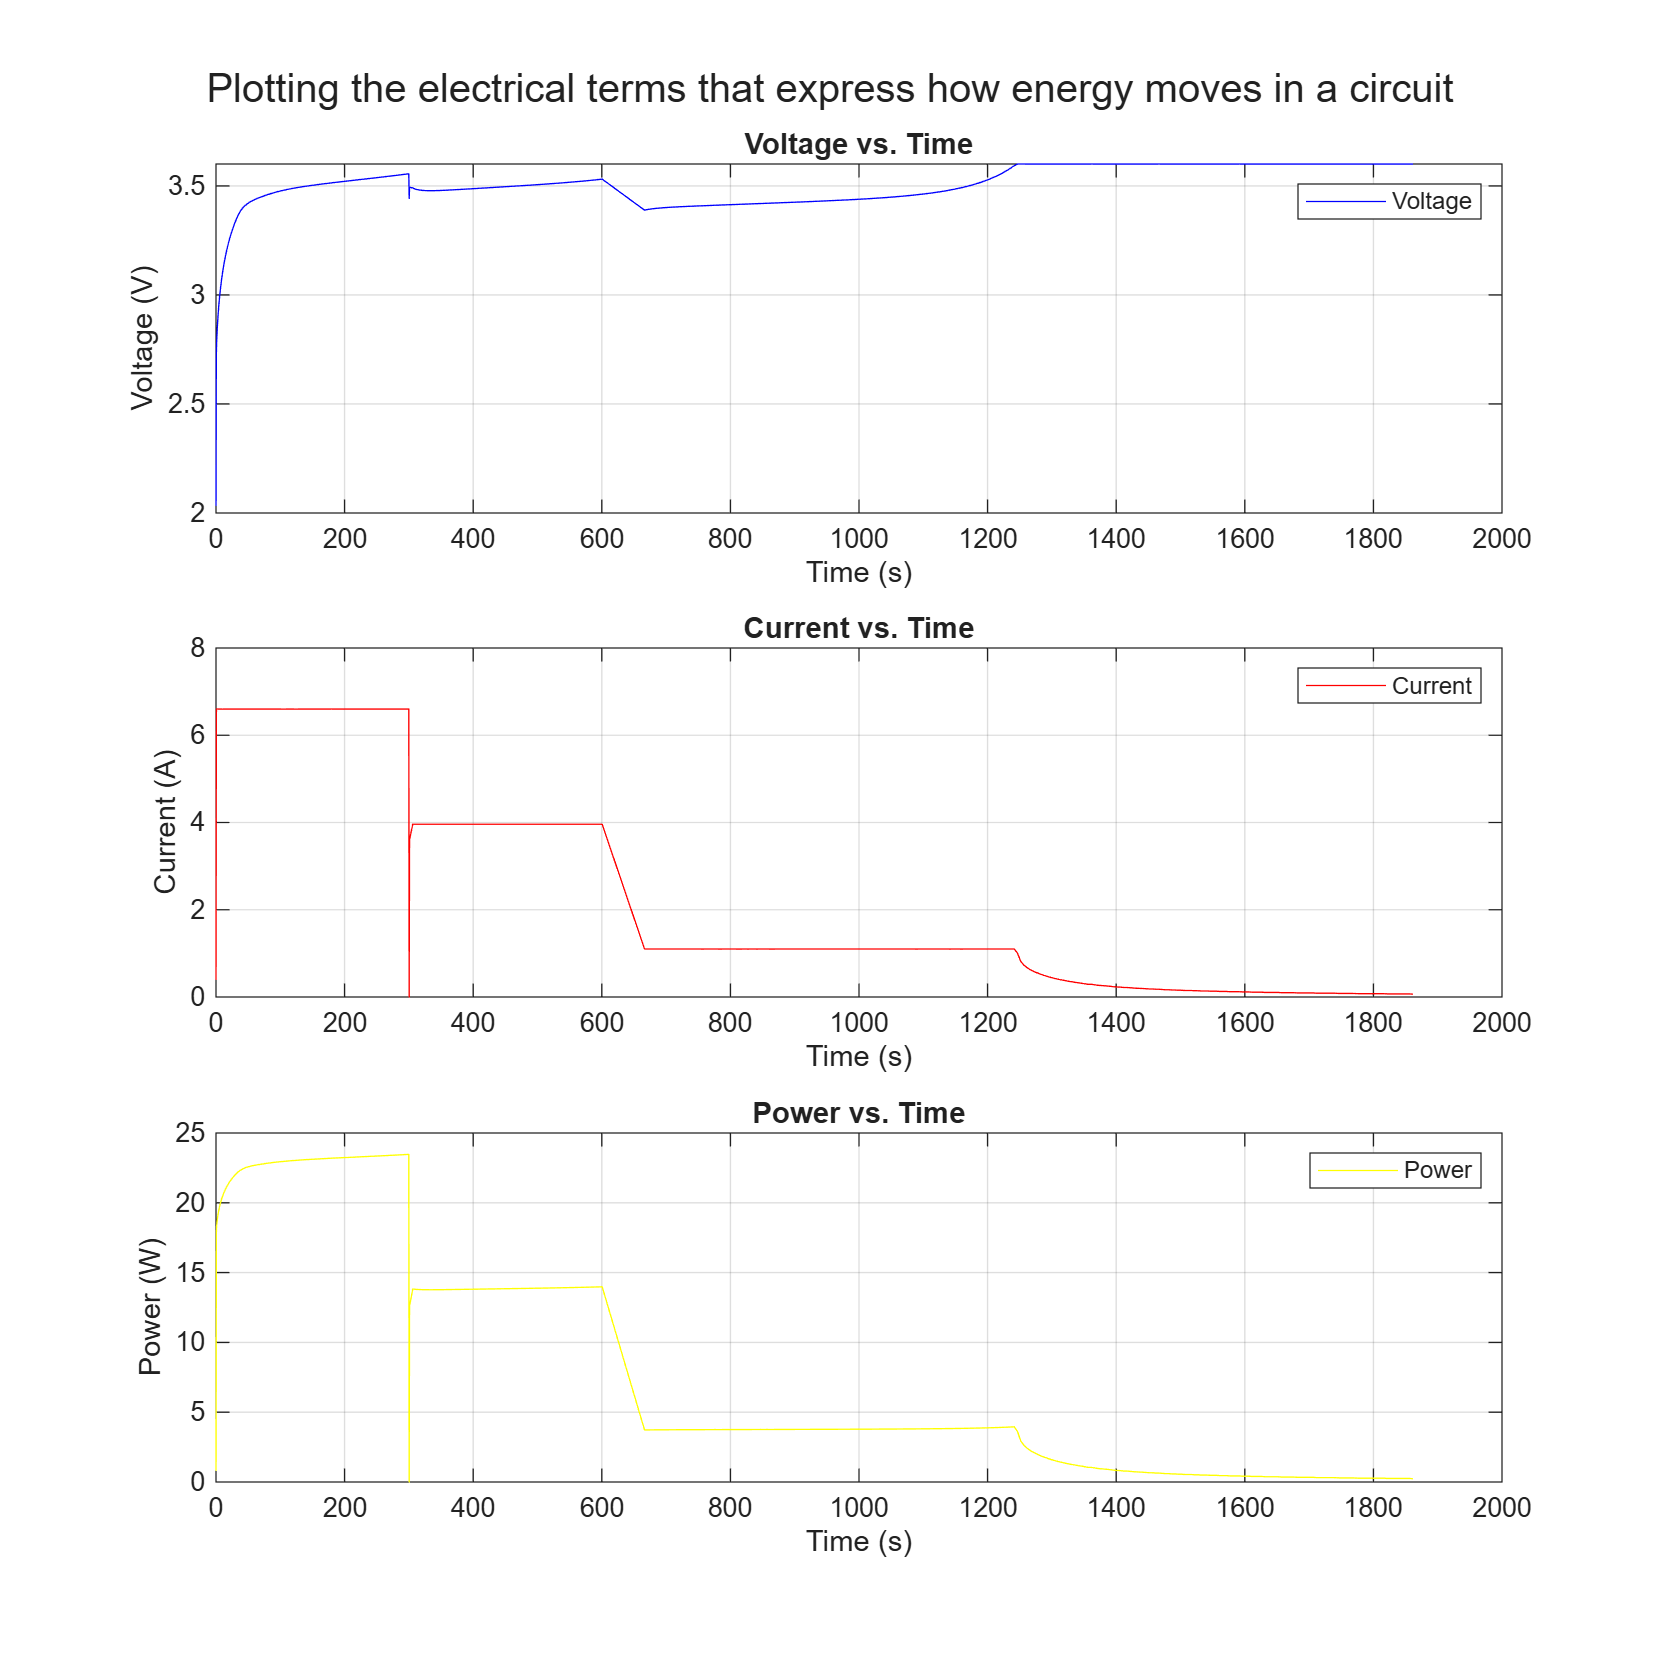

% Set current, voltage, and time variables to pull from the filtered chargingData
I = chargingData.Current;
V = chargingData.Voltage;
t = chargingData.TimeInSeconds;

% Calculate power by multiplying current and voltage
P = I .* V;

% Create a figure handle
figure('Name', 'Battery Charging Profile', 'Position', [0, 0, 1000, 1000]);

% STEP 1: Initialize the first subplot. Plot voltage vs. time.
subplot(3, 1, 1)
plot(t, V, 'b', 'DisplayName', 'Voltage')
title('Voltage vs. Time')
xlabel('Time (s)')
ylabel('Voltage (V)')
legend
grid on

% STEP 2: Use a second subplot to plot current vs. time.
subplot(3, 1, 2)
plot(t, I, 'r', 'DisplayName', 'Current')
title('Current vs. Time')
xlabel('Time (s)')
ylabel('Current (A)')
legend
grid on

% STEP 3: Use a third subplot to plot power vs time.
subplot(3, 1, 3)
plot(t, P, 'y', 'DisplayName', 'Power')
title('Power vs. Time')
xlabel('Time (s)')
ylabel('Power (W)')
legend
grid on

% Add a main title for the entire figure
sgtitle('Plotting the electrical terms that express how energy moves in a circuit')